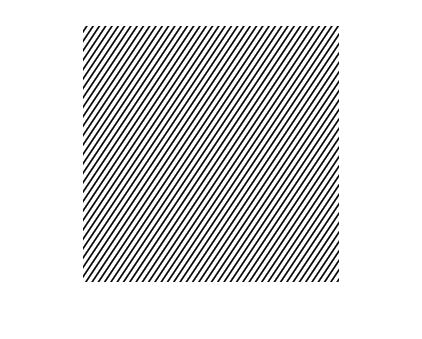

cam = imread("cameraman.tif");

[x,y] = meshgrid(1:256,1:256);

p = sin(x+y/1.5)+1;

imshow(p);

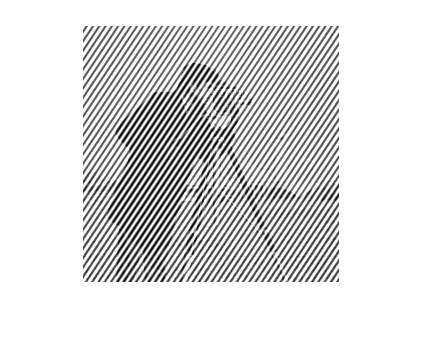


cp = (im2double(cam) + p) / 2;

imshow(cp);

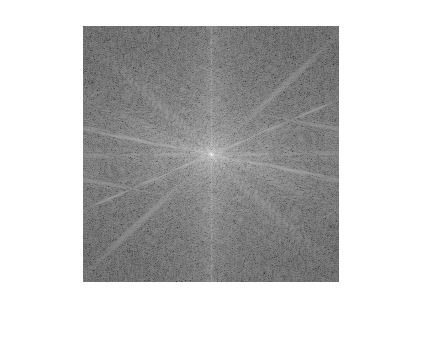


camf=  fftshift(fft2(cam));
fftshow(camf,'log');

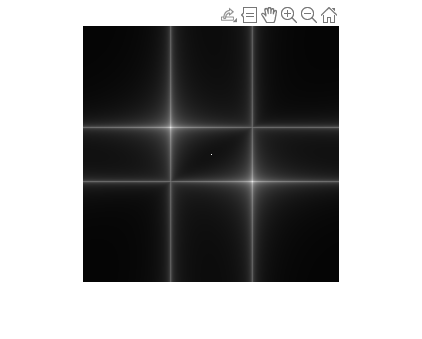


pf=  fftshift(fft2(p));
fftshow(pf,'log');

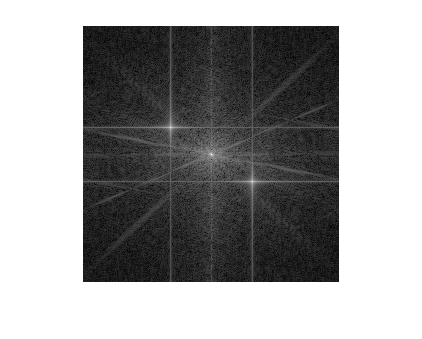


cpf=  fftshift(fft2(cp));
fftshow(cpf,'log');

Band Pass

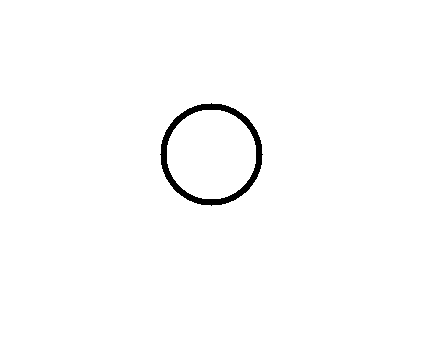

z = sqrt((x-129).^2 + (y-129).^2);

br = (z<45 | z>51);
imshow(br);

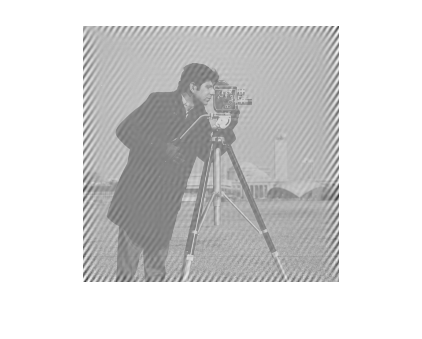


cpfbr = cpf.*br;
% fftshow(cpfbr);

cpfbri = ifft2(cpfbr);
fftshow(cpfbri,'log');

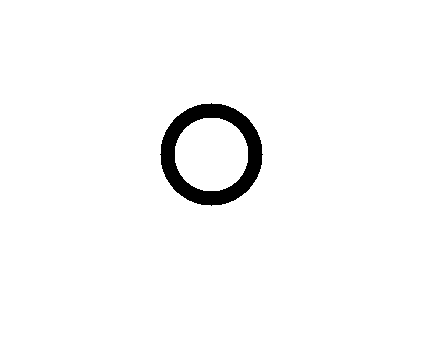

z = sqrt((x-129).^2 + (y-129).^2);

br = (z<37 | z>51);
imshow(br);

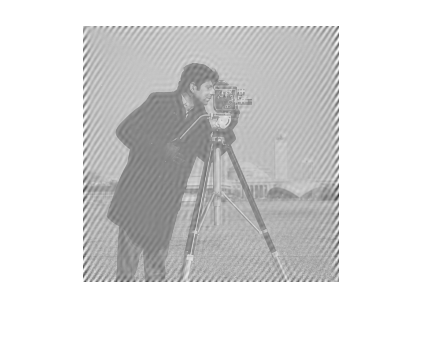


cpfbr = cpf.*br;
% fftshow(cpfbr);

cpfbri = ifft2(cpfbr);
fftshow(cpfbri,'log');

Notch Filtering

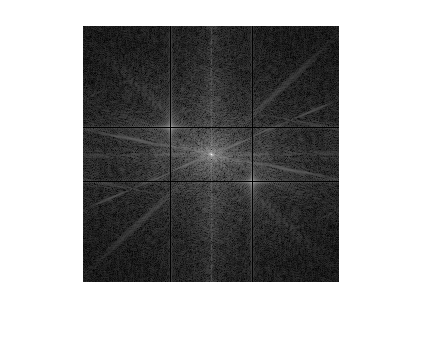

cpf=  fftshift(fft2(cp));

cpf(156,:) = 0;
cpf(102,:) = 0;
cpf(:,170) = 0;
cpf(:,88) = 0;

fftshow(cpf,'log');

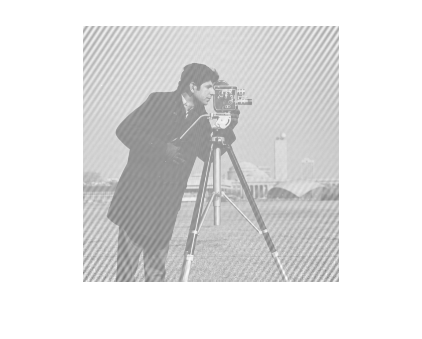

% br = (z<47 | z>51);

% cpf_BP_NOTCH = cpf.*br;

inverse_notch = ifft2(cpf);
fftshow(inverse_notch,'log');

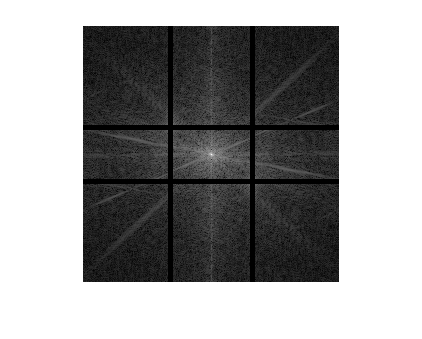

cpf=  fftshift(fft2(cp));

cpf(154:158,:) = 0;
cpf(100:104,:) = 0;
cpf(:,168:172) = 0;
cpf(:,86:90) = 0;
fftshow(cpf,'log');

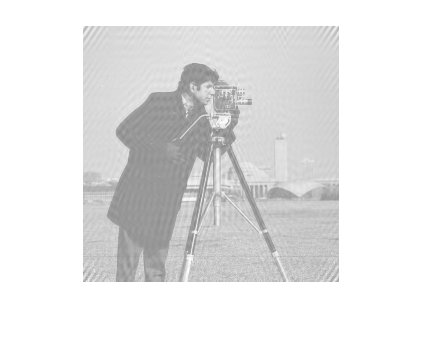

%br = (z<47 | z>51);

% cpf_BP_NOTCH = cpf.*br;

inverse_notch = ifft2(cpf);
fftshow(inverse_notch,'log');